load set3.dat

X1 = set3;

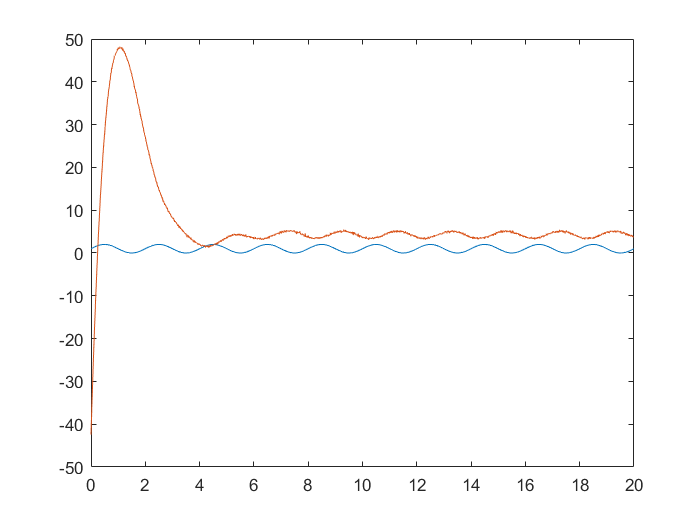

% Plot X1 and X2
% X1 is a step response while X2 is a u(t) - u(t-1) 

plot(X1(:,1),X1(:,2))
hold on
plot(X1(:,1),X1(:,3)) 
hold off

% Since T = 200, choose w > 2 pi/200
% Choose values of Start and Final so we have a whole number of periods

[Y1, W1] = trimLowpass(X1, 801, 2000, 0.04, 2);

%Centre about zero
Y = Y1(:,2) - mean(Y1(:,2));
W = W1 - mean(W1);

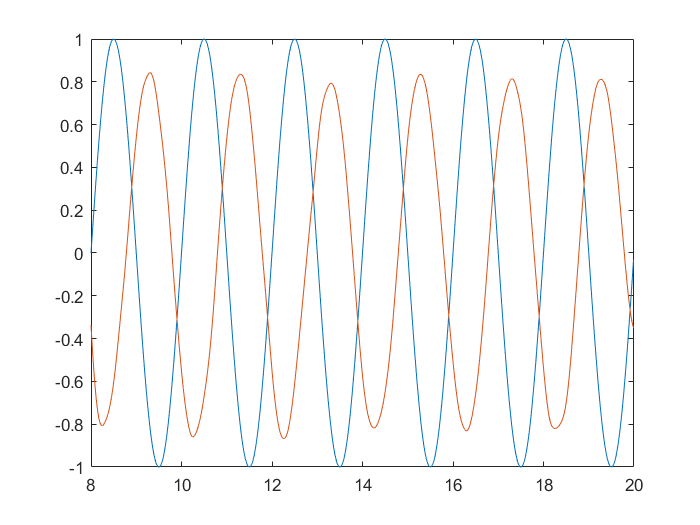

% Plot trimmed and filtered data
plot(Y1(:,1),Y)
hold on;
plot(Y1(:,1), W) % Gives a plot of the input vs. sample number 
hold off;

% Find rms value of Y1 and W1
rms = @(v) sqrt(mean(v.^2))

rms = function_handle with value:
    @(v)sqrt(mean(v.^2))



W_rms = rms(W)

W_rms = 0.5899

Y_rms = rms(Y)

Y_rms = 0.7071


gain = W_rms/Y_rms

gain = 0.8343

% Find zero crossings
zci = @(v) find(diff(sign(v)));

W_zc = zci(W)

W_zc =     79
   179
   280
   379
   478
   579
   680
   780
   879
   980


Y_zc = zci(Y)

Y_zc =      1
   100
   101
   200
   201
   300
   301
   400
   401
   500
